# Introduction to MATLAB

MATLAB (Matrix Laboratory) is a high-level programming language and environment used for numerical computation, data analysis, visualization, and algorithm development. It's widely used in engineering, science, and mathematics.

## 0. How to Download

[https://www.nyu.edu/life/information-technology/computing-support/software/software/matlab.html](https://www.nyu.edu/life/information-technology/computing-support/software/software/matlab.html)

Free for eligible NYU community members

## 1. MATLAB Interface

When you open MATLAB, you will see several key sections:

Command Window: Where you can type commands and execute code.

Workspace: Displays variables you have created.

Current Folder: Shows files in the working directory.

Editor: Where you write and save scripts.

## 2. Basic Commands

For people who use multiple coding languages , the most important thing to note is: in MATLAB, the percent symbol is used for comments, and a semicolon should be added at the end of each statement.

% Variables: You can assign values to variables without 
% declaring their types.
x = 5; 
y = 7; 
z = 6 

z = 6


%Arithmetic Operations: MATLAB uses common arithmetic symbols.
a = 5 + 3;     % addition
b = 10 - 4;    % subtraction
c = 6 * 7;     % multiplication
d = 20 / 5;    % division
e = 2^3;       % exponentiation


## 3. Matrices and Arrays

MATLAB is primarily designed for matrix manipulation, and arrays are a core part of its functionality.

%% Creation
% 1D Array (Vector)
rowVec = [1, 2, 3, 4];
colVec = [1; 2; 3; 4];

% 2D Array (Matrix)
M = [1, 2, 3; 4, 5, 6; 7, 8, 9];

% using colon operator. [start:step:end]
test1=1:10;
test2=1:2:10;
test3=10:-1:1;

% using linspace
x_array=linspace(0,1,10);

%% Matrix Indexing
% Access an element (2nd row, 3rd column)
element = M(2, 3);

% Access a whole row (1st row)
row = M(1, :);

% Access a whole column (2nd column)
column = M(:, 2);

% Modify an element (set 2nd row, 3rd column to 10)
M(2, 3) = 10;

% matrix transpose
MT=M';

%% Matrix Multiplication
% Multiply two matrices
A = [1, 2; 3, 4];
B = [5, 6; 7, 8];
C = A * B  % Matrix multiplication

C =     19    22
    43    50



% element-wise multiplication
D = A .* B

D =      5    12
    21    32


## 4. Control Flow


% If-Else statement
x = 10;
if x > 0
    disp('x is positive');
else
    disp('x is non-positive');
end

x is positive


% For loop
for i = 1:5
    disp(['Iteration: ', num2str(i)]);
end

Iteration: 1
Iteration: 2
Iteration: 3
Iteration: 4
Iteration: 5


% While loop
n = 0;
while n < 5
    disp(['n is ', num2str(n)]);
    n = n + 1;
end

n is 0
n is 1
n is 2
n is 3
n is 4


## 5. Scripts and Functions

`.m` files are plain text files that contain MATLAB code. They are primarily used for writing scripts and functions in MATLAB. These files are more traditional and are ideal for writing simple, linear code.

`.mlx` files, also called **Live Scripts**, are more interactive. They provide an enhanced environment for working with code interactively and visualizing the results immediately.


% Call the function
result = func(4);  % result = 8
result

result = 8

%Inline functions 
% easy for defining simple mathematical expressions quickly.
new_func_exp1=@(x)2*x;
new_func_exp2=@(x,y,z)x*y+z;

new_func_exp1(4)

ans = 8

new_func_exp2(1,2,3)

ans = 5

## 6. Plotting

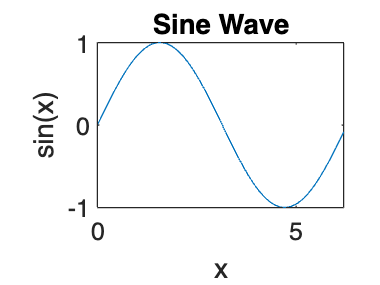


x = 0:0.1:2*pi;   % Create a range of x values from 0 to 2*pi
y = sin(x);       % Compute the sine of x
plot(x, y);       % Plot y against x
title('Sine Wave');  % Add a title
xlabel('x');         % Label x-axis
ylabel('sin(x)');    % Label y-axis

## 7. Help and Documentation

% To get help on any function, use the help command:
help plot  % Displays help for the plot function

 plot - 2-D line plot
    This MATLAB function creates a 2-D line plot of the data in Y versus the
    corresponding values in X.

    Vector and Matrix Data
      plot(X,Y)
      plot(X,Y,LineSpec)
      plot(X1,Y1,...,Xn,Yn)
      plot(X1,Y1,LineSpec1,...,Xn,Yn,LineSpecn)
      plot(Y)
      plot(Y,LineSpec)

    Table Data
      plot(tbl,xvar,yvar)
      plot(tbl,yvar)

    Additional Options
      plot(ax,___)
      plot(___,Name,Value)
      p = plot(___)

    Input Arguments
      X - x-coordinates
        scalar | vector | matrix
      Y


% You can also use the doc command to open the documentation in a web browser:
doc plot

% Meanwhile LLM is also a good teacher.